% Assign the data table
Tbl = DataSetv2;

% Display the first lines
disp(Tbl(1:5, :));

    Age    YrsSinceDiagnosis    UDPRSOn    LEDMg_totalDaily_    SampleENOnMedAverage
    ___    _________________    _______    _________________    ____________________

    75             6              18              600                   121         
    75             6              18              600                   152         
    75             6              18              600                   176         
    75             6              18              600                   136         
    79             2              32              250                    78         






% Extract numeric data for correlation analysis
numericData = Tbl{:, vartype('numeric')}; % Extract all numeric columns
numericData = array2table(numericData, 'VariableNames', Tbl.Properties.VariableNames(vartype('numeric')));

% Compute and plot
[R, PValue, H] = corrplot(numericData, 'type', 'Pearson', 'testR', 'on', 'varNames', numericData.Properties.VariableNames);

% Display the correlation matrix and p-values
disp('Correlation Matrix:');

Correlation Matrix:


disp(R);

                               Age       YrsSinceDiagnosis    UDPRSOn     LEDMg_totalDaily_    SampleENOnMedAverage
                            _________    _________________    ________    _________________    ____________________

    Age                             1         -0.13331        0.021668        -0.13446              -0.092649      
    YrsSinceDiagnosis        -0.13331                1        -0.36003         0.39641              0.0060428      
    UDPRSOn                  0.021668         -0.36003               1        -0.22741               -0.32197      
    LEDMg_totalDaily_        -0.13446          0.39641        -0.22741               1                -0.3138      
    SampleENOnMedAverage    -0.092649        0.0

disp('P-Values:');

P-Values:


disp(PValue);

                              Age      YrsSinceDiagnosis     UDPRSOn      LEDMg_totalDaily_    SampleENOnMedAverage
                            _______    _________________    __________    _________________    ____________________

    Age                           1          0.21564           0.84118          0.21166               0.39059      
    YrsSinceDiagnosis       0.21564                1        0.00057022       0.00013163               0.95544      
    UDPRSOn                 0.84118       0.00057022                 1         0.033102             0.0022205      
    LEDMg_totalDaily_       0.21166       0.00013163          0.033102                1             0.0029091      
    SampleENOnMedAverage    0.39059          0.9

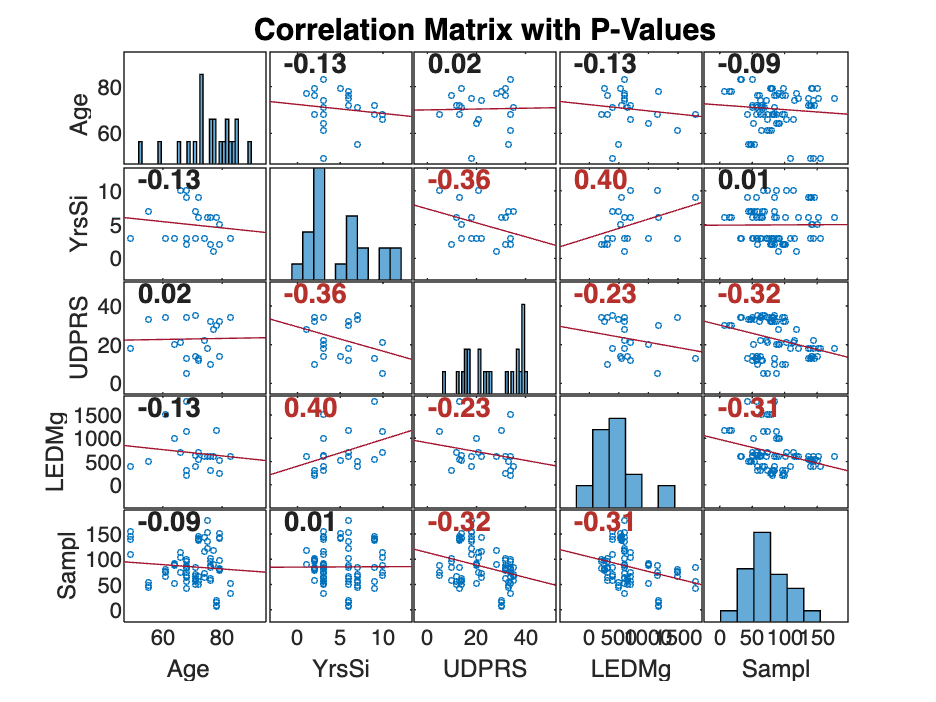


% Use the handles to customize the plot
title('Correlation Matrix with P-Values');

% Customize further
grid on;
colormap('jet');